clear;clc;close all;


e = 0;
f = -1;
g = 1;
h = 0;
j = 1;
k = 0;
Tvec = 0:10;
T = 10;
N = 100;


answervec = EMsolver(e,f,g,h,j,k,T,N)

answervec =     1.0000    1.0000    0.9900    0.9700    0.9401    0.9005    0.8515    0.7935    0.7270    0.6525    0.5708    0.4825    0.3886    0.2898    0.1871    0.0816   -0.0259   -0.1341   -0.2421   -0.3488   -0.4530   -0.5538   -0.6500   -0.7407   -0.8248   -0.9016   -0.9701   -1.0296   -1.0794   -1.1190   -1.1477   -1.1652   -1.1712   -1.1656   -1.1483   -1.1193   -1.0789   -1.0272   -0.9648   -0.8921   -0.8097   -0.7185   -0.6191   -0.5125   -0.3998   -0.2819   -0.1600   -0.0353    0.0910    0.2176


length(answervec)

ans = 101


improvedvec = IEMsolver(e,f,g,h,j,k,T,N)

improvedvec =     1.0000    0.9950    0.9850    0.9650    0.9352    0.8958    0.8470    0.7892    0.7230    0.6489    0.5675    0.4797    0.3862    0.2879    0.1857    0.0806   -0.0263   -0.1340   -0.2415   -0.3476   -0.4513   -0.5515   -0.6472   -0.7374   -0.8211   -0.8975   -0.9656   -1.0248   -1.0743   -1.1136   -1.1421   -1.1595   -1.1654   -1.1598   -1.1425   -1.1136   -1.0733   -1.0218   -0.9597   -0.8873   -0.8053   -0.7144   -0.6155   -0.5094   -0.3972   -0.2799   -0.1586   -0.0345    0.0911    0.2172



dt = T/N;

Tvec = 0:dt:10;
length(improvedvec)

ans = 101

length(Tvec)

ans = 101

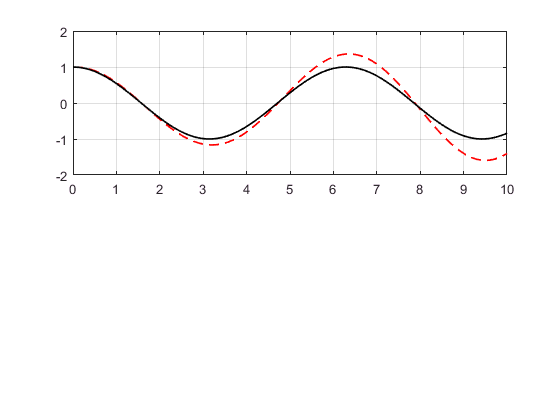


figure
subplot(2,1,1)


plot(Tvec, improvedvec,'--r','Linewidth',1.25)
hold on

plot(Tvec, cos(Tvec), '-k','Linewidth',1.25)
grid on 

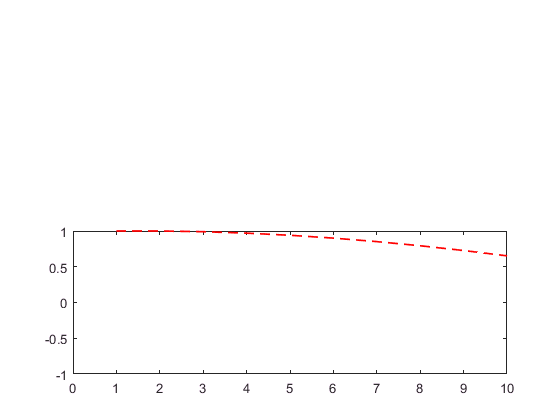

figure
subplot(2,1,2)
plot(answervec,'--r','Linewidth',1.25)
hold on
plot(Tvec, sin(T), '-k','Linewidth',1.25)
xlim([0 10])

function [x y] = IEMsolver(e,f,g,h,j,k,T,N)
 A = [e f; g h];
 dt = T/N;
 t = 0:dt:T;

 SOL = NaN(2,length(t));
 SOLIMPROVED = NaN(2, length(t));
 
 SOL(1,1) = j;
 SOL(2,1) = k;
 
  
 SOLIMPROVED(1,1) = j;
 SOLIMPROVED(2,1) = k;

 for(k = 2:length(t))
 SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
 
 %sol improved 
 SOLIMPROVED(:,k) = SOL(:,k-1) + (dt/2)*(A*SOL(:,k-1) + A*SOL(:,k));
 
 end

 x = SOLIMPROVED(1,:);
 y = SOLIMPROVED(2,:);
end


function [x y] = EMsolver(e,f,g,h,j,k,T,N)
 A = [e f; g h];
 dt = T/N;
 t = 0:dt:T;

 SOL = NaN(2,length(t));
 SOL(1,1) = j;
 SOL(2,1) = k;

 for(k = 2:length(t))
 SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
 end

 x = SOL(1,:);
 y = SOL(2,:);
end